# Pitch angle and position Loop PID Tuning

clc; clear; close all;
%% Parameters
m = 1.5; Cv = 0.1; Cw = 0.01; Jy = 3e-2; g = 9.81;
Ts = 0.005;   % 5 ms

s = tf('s');

% Inner plant: M -> w
G_inner_c = 1/(Jy*s + Cw);
G_inner   = c2d(G_inner_c, Ts, 'zoh');

% Angle plant: w -> phi
G_phi = c2d(1/s, Ts, 'tustin');

% Velocity plant: phi -> v  (approx g*cos(phi) ≈ g*(1 - phi^2/2) ~ g*phi for small angles)
G_vphi = c2d(g/s, Ts, 'tustin'); 

% Position plant: v -> x
G_x = c2d(1/s, Ts, 'tustin');

%% Tunable PIDs
C_rate = tunablePID('C_rate','PID');   C_rate.Ts = Ts;
C_angle= tunablePID('C_angle','PID');  C_angle.Ts = Ts;
C_vel  = tunablePID('C_vel','PID');      C_vel.Ts = Ts;     % usually PID
C_pos  = tunablePID('C_pos','P');      C_pos.Ts = Ts;       % usually P


C_rate.Kp.Minimum = 0;  C_rate.Ki.Minimum = 0;  C_rate.Kd.Minimum = 0; C_rate.Tf.Minimum=1; C_rate.Tf.Maximum=1000;
C_angle.Kp.Minimum = 0;  C_angle.Ki.Minimum = 0;  C_angle.Kd.Minimum = 0; C_angle.Tf.Minimum=1; C_angle.Tf.Maximum=1000;
C_vel.Kp.Minimum = 0;  C_vel.Ki.Minimum = 0;  C_vel.Kd.Minimum = 0; C_vel.Tf.Minimum=1; C_vel.Tf.Maximum=1000;

C_pos.Kp.Minimum = 0;

%% Interconnect (sketch)
% phi_ref -> w_ref -> M -> w -> phi
% v_ref -> phi_ref
% x_ref -> v_ref

%% Naming I/Os
% Controllers
C_pos.InputName   = 'e_x';     C_pos.OutputName   = 'v_ref';
C_vel.InputName   = 'e_v';     C_vel.OutputName   = 'phi_ref';
C_angle.InputName = 'e_phi';   C_angle.OutputName = 'w_ref';
C_rate.InputName  = 'e_w';     C_rate.OutputName  = 'M_ctrl';

% Plants
G_x.InputName     = 'v';       G_x.OutputName     = 'x';
G_vphi.InputName  = 'phi';     G_vphi.OutputName  = 'v';
G_phi.InputName   = 'w';       G_phi.OutputName   = 'phi';
G_inner.InputName = 'M';       G_inner.OutputName = 'w';

% Summing junctions
Sum_x   = sumblk('e_x   = x_ref   - x');
Sum_v   = sumblk('e_v   = v_ref   - v');
Sum_phi = sumblk('e_phi = phi_ref - phi');
Sum_w   = sumblk('e_w   = w_ref   - w');

% Disturbance torque
Sum_M   = sumblk('M = M_ctrl + M_dist');

%% Interconnection
CL0 = connect(C_pos,C_vel,C_angle,C_rate, ...
              G_x,G_vphi,G_phi,G_inner, ...
              Sum_x,Sum_v,Sum_phi,Sum_w,Sum_M, ...
              'x_ref','x', ...
              {'e_x','e_v','e_phi','e_w','M','w_ref'});   % analysis points

%% Goals
% Tracking only for outermost position (lets inner refs stay internal)
tau_pos = 0.5;   % ~2.0*tau to 4.0*tau is settling heuristic; adjust as you like
ReqTrackPos = TuningGoal.Tracking('x_ref','x', tau_pos);

% Loop-shape robustness/bandwidth goals (choose crossovers)
wc_rate  = 2*pi*6;    % ~6 Hz
wc_angle = 2*pi*2;    % ~2 Hz
wc_vel   = 2*pi*0.6;  % ~0.6 Hz
wc_pos   = 2*pi*0.2;  % ~0.2 Hz

s = tf('s');   % <-- ensure this exists right here
% ReqLS_rate  = TuningGoal.LoopShape('e_w',   tf(wc_rate,  [1 0]));  % ~wc_rate/s
% ReqLS_angle = TuningGoal.LoopShape('e_phi', tf(wc_angle, [1 0]));
% ReqLS_vel   = TuningGoal.LoopShape('e_v',   tf(wc_vel,   [1 0]));
% ReqLS_pos   = TuningGoal.LoopShape('e_x',   tf(wc_pos,   [1 0]));

ReqLS_rate  = TuningGoal.LoopShape('e_w',   wc_rate/s);
ReqLS_angle = TuningGoal.LoopShape('e_phi', wc_angle/s);
ReqLS_vel   = TuningGoal.LoopShape('e_v',   wc_vel/s);
ReqLS_pos   = TuningGoal.LoopShape('e_x',   wc_pos/s);


% (Optional) You can weight the goals if tracking should dominate:
% WG = [10 1 1 1 1]; etc.

GOALS = [ReqTrackPos, ReqLS_rate, ReqLS_angle, ReqLS_vel, ReqLS_pos];

%% Tune
[CLtuned,fSoft] = systune(CL0, GOALS);

Final: Soft = 1.75, Hard = -Inf, Iterations = 41
       Some closed-loop poles are marginally stable (decay rate near 1e-07)


%% Inspect tuned gains
showTunable(CLtuned)

C_angle =
 
              Ts               1     
  Kp + Ki * ------ + Kd * -----------
              z-1         Tf+Ts/(z-1)

  with Kp = 16.9, Ki = 0.95, Kd = 6.26, Tf = 1, Ts = 0.005
 
Name: C_angle
Sample time: 0.005 seconds
Discrete-time PIDF controller in parallel form.
-----------------------------------
C_pos =
 
  Kp = 2.4
 
Name: C_pos
P-only controller.
-----------------------------------
C_rate =
 
              Ts               1     
  Kp + Ki * ------ + Kd * -----------
              z-1         Tf+Ts/(z-1)

  with Kp = 2.06, Ki = 4.11e-05, Kd = 0.0104, Tf = 1.34, Ts = 0.005
 
Name: C_rate
Sample time: 0.005 seconds
Discrete-time PIDF controller in parallel form.
-----------------------------------
C_vel =
 
              Ts               1     
  Kp + Ki * ------ + Kd * -----------
              z-1         Tf+Ts/(z-1)

  with Kp = 0.626, Ki = 1.25e-05, Kd = 0.718, Tf = 21.4, Ts = 0.005
 
Name: C_vel
Sample time: 0.005 seconds
Discrete-time PIDF controller in parallel f

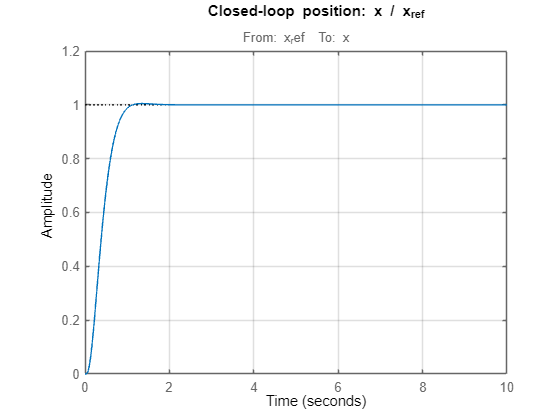

%% Closed-loop from x_ref to x
T_pos = getIOTransfer(CLtuned,'x_ref','x');
figure; step(T_pos, 10); grid on
title('Closed-loop position: x / x_{ref}')

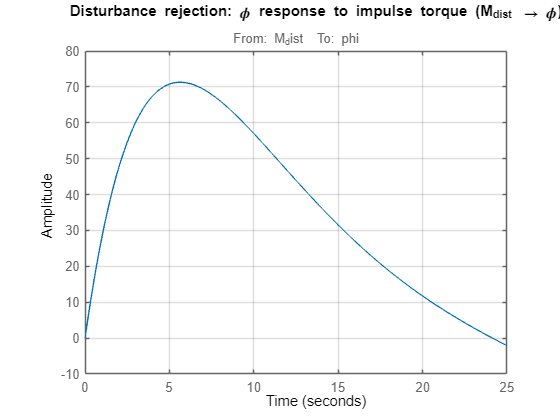

%% Disturbance rejection at angle (torque impulse)
% Build numeric closed loop with disturbance input
CLd = connect(C_pos,C_vel,C_angle,C_rate, ...
              G_x,G_vphi,G_phi,G_inner, ...
              Sum_x,Sum_v,Sum_phi,Sum_w,Sum_M, ...
              {'x_ref','M_dist'}, 'phi');

T_dist = CLd('phi','M_dist');   % phi response to torque disturbance
figure; impulse(T_dist,25); grid on
title('Disturbance rejection: \phi response to impulse torque (M_{dist} \rightarrow \phi)')

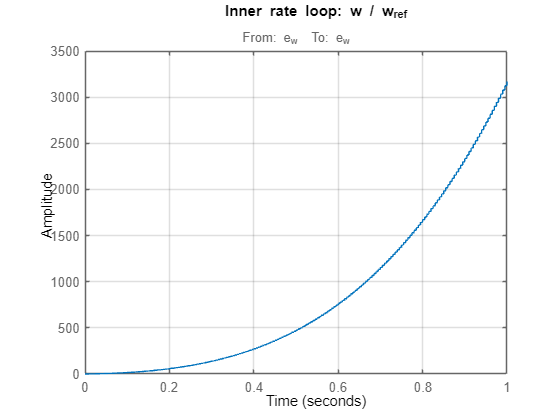

%% (Optional) sanity: inner loop step checks (hidden refs)
% These are internal but you can still extract from CLtuned by I/O names:
% T_rate  = getIOTransfer(CLtuned,'w_ref','w');
% T_angle = getIOTransfer(CLtuned,'phi_ref','phi');
% T_vel   = getIOTransfer(CLtuned,'v_ref','v');
% 

T_rate  = getLoopTransfer(CLtuned,'e_w',-1);   % inner loop
T_angle = getLoopTransfer(CLtuned,'e_phi',-1); % angle loop
T_vel   = getLoopTransfer(CLtuned,'e_v',-1);   % velocity loop
figure; step(T_rate, 1); grid on;  title('Inner rate loop: w / w_{ref}')

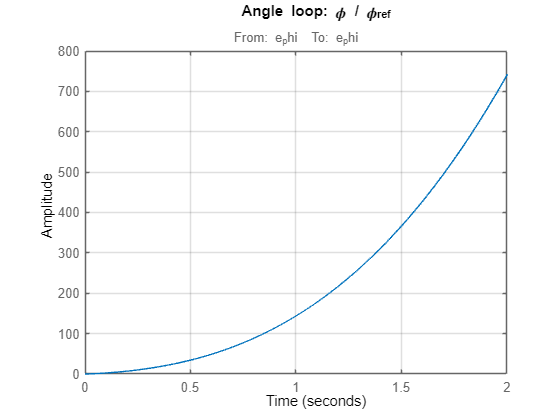

figure; step(T_angle,2); grid on;  title('Angle loop: \phi / \phi_{ref}')

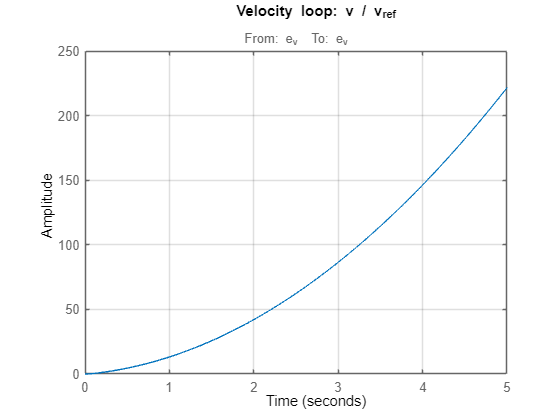

figure; step(T_vel,  5); grid on;  title('Velocity loop: v / v_{ref}')

%% Interconnection
CL0 = connect(C_pos,C_vel,C_angle,C_rate, ...
              G_x,G_vphi,G_phi,G_inner, ...
              Sum_x,Sum_v,Sum_phi,Sum_w,Sum_M, ...
              'x_ref', {'x','v','phi','w'}, ...   % expose all these as outputs
              {'e_x','e_v','e_phi','e_w','M','w_ref'});  % analysis points

T_rate  = getIOTransfer(CLtuned,'w_ref','w');

Error using genlti/getIOTransfer
The identifier "w" does not match any output signal. Valid output signal names include the model's output names and
its analysis points (see "getPoints").

T_angle = getIOTransfer(CLtuned,'phi_ref','phi');
T_vel   = getIOTransfer(CLtuned,'v_ref','v');

figure; step(T_rate, 1); grid on;  title('Inner rate loop: w / w_{ref}')
figure; step(T_angle,2); grid on;  title('Angle loop: \phi / \phi_{ref}')
figure; step(T_vel,  5); grid on;  title('Velocity loop: v / v_{ref}')
